# Set Table Column Width

This example shows how to set column widths for a DOM `Table` and `FormalTable`.

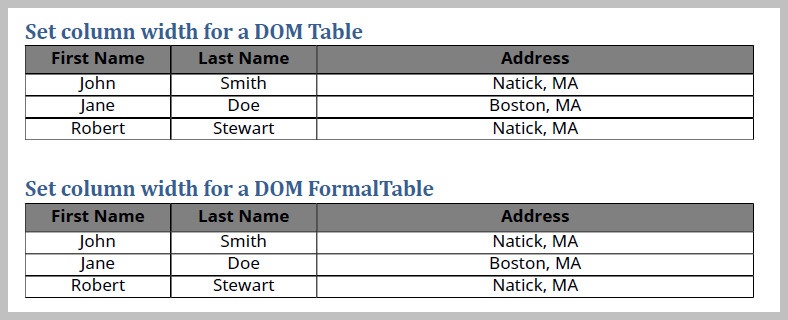

Import the DOM API package so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*

Create and open a document. To create a Word document, change the output type from `pdf` to `docx`. To create an HTML document, change `pdf` to `html` or `html-file` for a multifile or single-file document, respectively.

d = Document("mydoc","pdf");
open(d);

Define table, table entries, and header row styles, which will be used in the later sections.

tableStyle = ...
    { ...
    Width("100%"), ...
    Border("solid"), ...
    RowSep("solid"), ...
    ColSep("solid") ...
    };

tableEntriesStyle = ...
    { ...
    HAlign("center"), ...
    VAlign("middle") ...
    };

headerRowStyle = ...
    { ...
    InnerMargin("2pt","2pt","2pt","2pt"), ...
    BackgroundColor("gray"), ...
    Bold(true) ...
    };

Define content for the table header row and table body, which will be used later to create a three-column DOM `Table` and a `FormalTable`.

headerContent = ...
    { ...
    'First Name', 'Last Name', 'Address' ...
    };

bodyContent = ...
    { ...
    'John', 'Smith', 'Natick, MA'; ...
    'Jane', 'Doe', 'Boston, MA'; ...
    'Robert', 'Stewart', 'Natick, MA' ...
    };

The following code uses the DOM `TableColSpecGroup` to define styles for a group of columns in a table. Setting the `Span` property to `3` applies the group formatting to all three columns of the table. To format one or more adjacent table columns in the group, use the DOM `TableColSpec` objects. The first `TableColSpec` object, `specs(1)`, spans to the first `2` columns in the group. Set the `Width` format in its `Style` property to make each of these two columns `20%` of the table width. The second `TableColSpec` object, `specs(2)`, spans to a single column, that is, the third column in the group, and is formatted to be `60%` of the table width.

grps(1) = TableColSpecGroup;
grps(1).Span = 3;

specs(1) = TableColSpec;
specs(1).Span = 2;
specs(1).Style = {Width("20%")};

specs(2) = TableColSpec;
specs(2).Span = 1;
specs(2).Style = {Width("60%")};

grps(1).ColSpecs = specs;

The following code appends a heading and a DOM `Table` to the document. Assigning the `grps`, created in the above code, to the `ColSpecGroups` property of the table, makes the first 2 columns 20% and the third column 60% of the table width. The code also assigns styles for the table, table entries, and the first row of the table.

append(d,Heading1("Set column width for a DOM Table"));

tableContent = [headerContent; bodyContent];

table = Table(tableContent);
table.ColSpecGroups = grps;

table.Style = tableStyle;
table.TableEntriesStyle = tableEntriesStyle;

firstRow = table.Children(1);
firstRow.Style = headerRowStyle; 

append(d,table);

The following code appends a heading and a DOM `FormalTable` to the document. Assigning the `grps` to the `ColSpecGroups` property of the formal table makes the first 2 columns 20% and the third column 60% of the table width. The code also assigns styles for the formal table, table entries, and the header row of the formal table.

append(d,Heading1("Set column width for a DOM FormalTable"));

formalTable = FormalTable(headerContent,bodyContent);
formalTable.ColSpecGroups = grps;

formalTable.Style = tableStyle;
formalTable.TableEntriesStyle = tableEntriesStyle;

headerRow = formalTable.Header.Children;
headerRow.Style = headerRowStyle; 

append(d,formalTable);

Close and view the document.

close(d);
rptview(d);

*Copyright 2018 The MathWorks, Inc.*